# Demo Dynamic Systems and Control Theory

Demo to show the basics of a dynamic system, closed loop, resonances and filters.

Every parameter can be changed to see the effects. The nominal ones are for show.

clear
close all
clc


## 1. Simulate 2nd order dynamic system

Choose frequency and damping for this system:

freq_sys1 = 10; % [Hz]
zeta_sys1 = 0.1;

sys_dyn1 = make_dynsys_poles(freq_sys1, zeta_sys1);

Choose a set of frequencies to simulate the responce to:

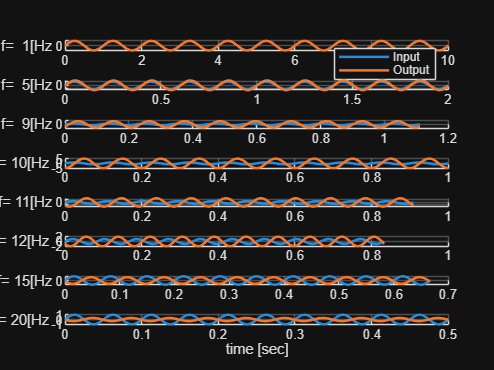

freq_4sim = [1 5 9 10 11 12 15 20];
len_f = length(freq_4sim);

fid_sin_resp = figure;

for indf = 1:len_f
    inp.f = freq_4sim(indf);
    sim_out = simulate_sin_inp_an(inp, sys_dyn1);

    % plot excitation and responce
    subplot(len_f, 1, indf); hold on
    plot(sim_out.t, sim_out.u, LineWidth=1.5, DisplayName='Input')
    plot(sim_out.t, sim_out.y, LineWidth=1.5, DisplayName='Output')
    grid on
    ylbl = sprintf('f=%3.0f[Hz', freq_4sim(indf));
    ylabel(ylbl, Rotation=0)
end
xlabel('time [sec]')
subplot(len_f,1,1)
legend show

## Functions

### 1. make_dynsys_poles creates a second order low pass filter. Only the poles are used and the gain is normalized to 1.

function sys = make_dynsys_poles(freq, zeta)

omega = 2*pi*freq;

num = [omega^2];
den = [1, 2*zeta*omega, omega^2];

sys = tf(num, den);

end


2. Simulate dynamic behavior of a system in responce to sinus exitation

function out = simulate_sin_inp_an(inp, sys_dyn)

f = inp.f;
w = 2*pi*f;
T = 1/f;

H = freqresp(sys_dyn,w);
amp = abs(H); phase=angle(H);

% NOTE: parameterize this
t_max = T*10; %Time of simulation will be exitation for 10 cycles
t = 0:0.0005:t_max;

u = sin(w*t);           % excitation signal
y = amp*sin(w*t+phase); % responce signal

out.t = t;
out.u = u;
out.y = y;

end